adsTrain = audioDatastore(fullfile('Daten', 'Sprachkommandos', 'train'), ...
   "IncludeSubfolders",true, 'LabelSource','foldernames');
adsTest = audioDatastore(fullfile('Daten', 'Sprachkommandos', 'test'), ...
   "IncludeSubfolders",true, 'LabelSource','foldernames');
% Klassenverteilung der Trainingsdaten auflisten:
tabulate(adsTrain.Labels);

  Value    Count   Percent
     go      750     25.00%
   left      750     25.00%
  right      750     25.00%
   stop      750     25.00%


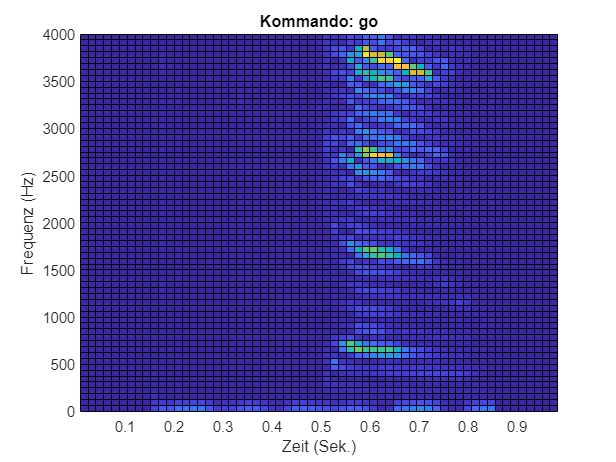

[~, fs] = audioread(adsTrain.Files{1});
win = hamming(128); 
[y, i] = adsTrain.read(); 
[specMat, f,t] = spectrogram(y, win, 0, length(win), fs); 
figure; 
pcolor(t, f, abs(specMat));
title(sprintf('Kommando: %s', i.Label)); 
xlabel('Zeit (Sek.)'), ylabel('Frequenz (Hz)');

C = length(categories(adsTrain.Labels));    % Anzahl Klassen
nTrain = length(adsTrain.Labels);
nTest = length(adsTest.Labels);
P = numel(specMat);      % Anzahl Merkmale


count = 0; 
trainMat = zeros(65, 62, 1, nTrain);
adsTrain.reset();     % Lesepointer auf Anfang setzen
tic
while adsTrain.hasdata()
   % disp(count);
   count = 1 + count;
   [y, i] = adsTrain.read(); 
   assert(i.SampleRate == 8000);   % Haben alle Dateien die gleiche Abtastrate? 
   % Spectrogramm erzeugen und in trainMat schreiben...
   [sm, f, t] = spectrogram(y, win, 0, length(win), i.SampleRate); 
   % TODO: ab hier weiter machen!
   trainMat(:, :, 1, count) = sm;
end

toc

Elapsed time is 21.456441 seconds.


assert(count == nTrain);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       21.88% |       1.7707 |          0.0100 |
|       1 |          50 |       00:00:01 |       31.25% |       1.2651 |          0.0100 |
|       2 |         100 |       00:00:02 |       46.88% |       1.1435 |          0.0100 |
|       2 |         150 |       00:00:03 |       75.00% |       0.7571 |          0.0100 |
|       3 |         200 |       00:00:03 |       84.38% |       0.5264 |          0.0100 |
|       3 |         250 |       00:00:04 |       71.88% |       0.6622 |          0.0100 |
|       4 |         300 |  

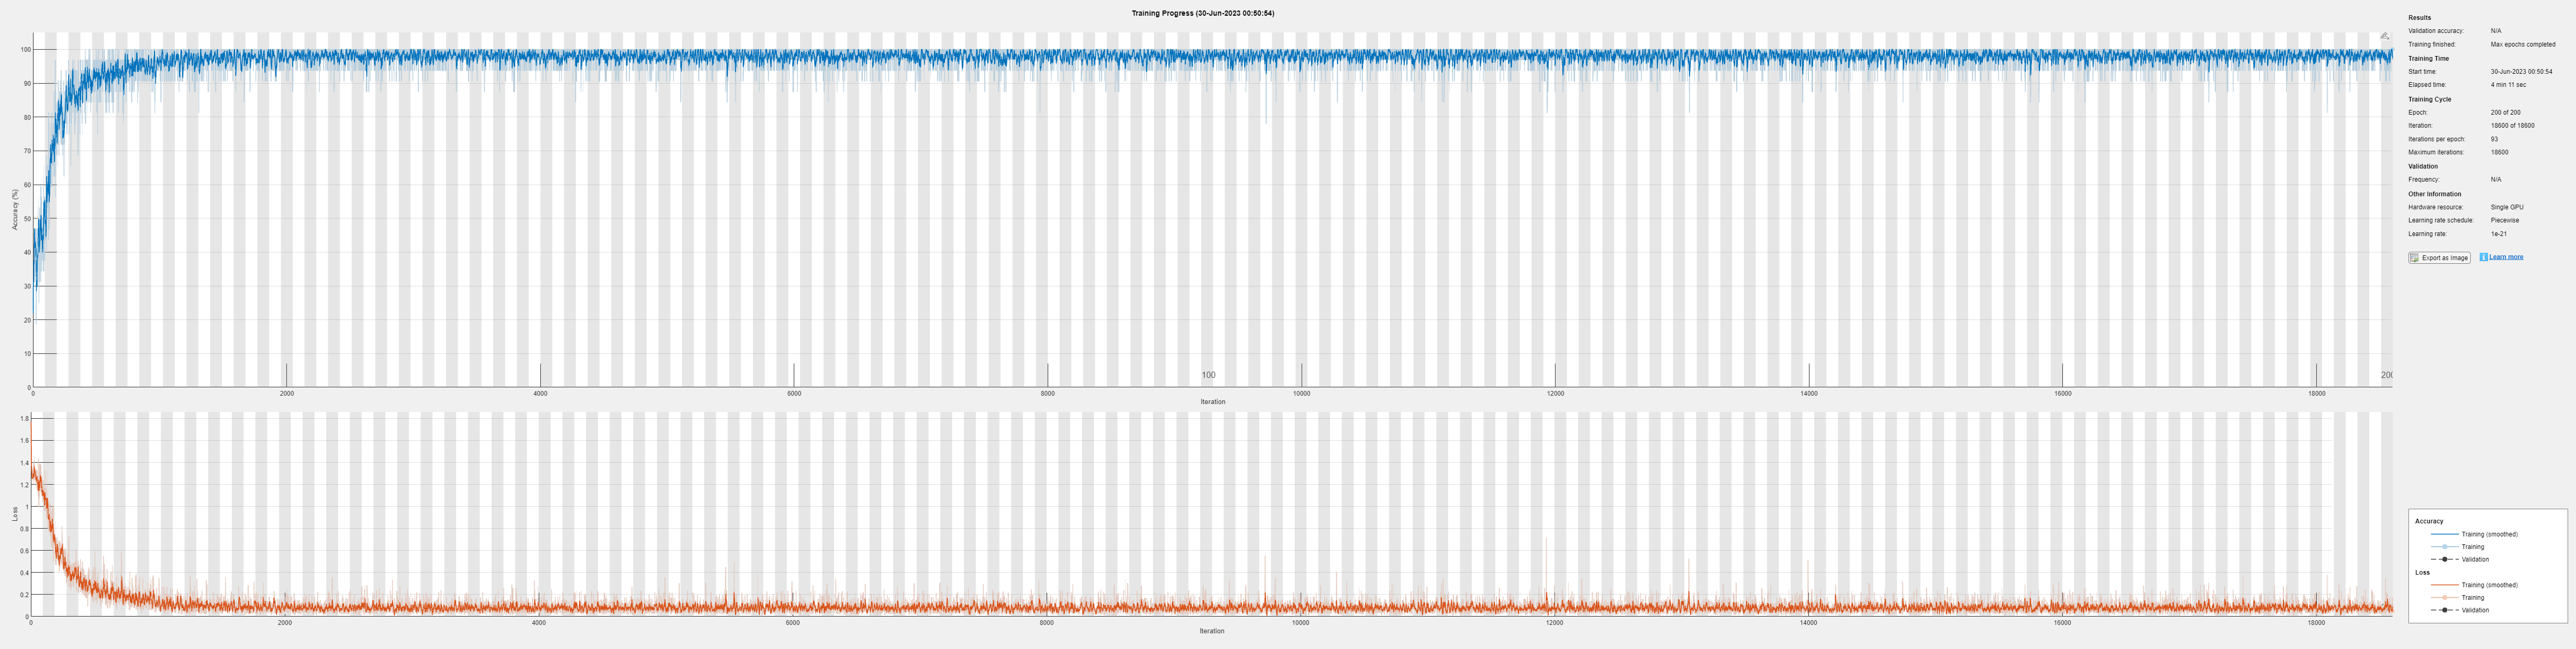

lambda = 1e-8;


layers = [
    imageInputLayer([65 62 1])
    convolution2dLayer(3, 128, 'Padding', 'same')
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    convolution2dLayer(3, 128, 'Padding', 'same')
    reluLayer
    dropoutLayer
    maxPooling2dLayer(2, 'Stride', 2)
    convolution2dLayer(3, 128)
    maxPooling2dLayer(3, "Stride", 2)
    reluLayer
    convolution2dLayer(3, 512, 'Padding', 'same')
    reluLayer
    dropoutLayer
    maxPooling2dLayer(2, 'Stride', 2)
    fullyConnectedLayer(4096)
    reluLayer
    fullyConnectedLayer(4)
    batchNormalizationLayer
    softmaxLayer
    classificationLayer
];

options = trainingOptions('sgdm', 'MaxEpochs', 200, 'L2Regularization', lambda, 'MiniBatchSize', 32, 'Plots', 'training-progress', 'Shuffle', 'every-epoch', 'InitialLearnRate', 0.01, 'LearnRateSchedule', 'piecewise', 'LearnRateDropPeriod', 10, 'LearnRateDropFactor', 0.1);
net_speechcommand = trainNetwork(abs(trainMat), adsTrain.Labels, layers, options);


count = 0; 
testMat = zeros(65, 62, 1, nTest);
adsTest.reset();     % Lesepointer auf Anfang setzen
tic
while adsTest.hasdata()
   % disp(count);
   count = 1 + count;
   [y, i] = adsTest.read(); 
   assert(i.SampleRate == 8000);   % Haben alle Dateien die gleiche Abtastrate? 
   % Spectrogramm erzeugen und in trainMat schreiben...
   [sm, f, t] = spectrogram(y, win, 0, length(win), i.SampleRate); 
   % TODO: ab hier weiter machen!
   testMat(:, :, 1, count) = sm;
end

toc

Elapsed time is 22.965700 seconds.


assert(count == nTest);

tic
[yneu, pMat] = classify(net_speechcommand, abs(testMat));
toc

Elapsed time is 0.531791 seconds.



testErr = sum(yneu ~= adsTest.Labels) / length(adsTest.Labels);
sprintf("%f", testErr)

ans = "0.038333"